%第一次作业习题3 第三种方案
%直接对这三种水果进行识别 隐含层神经元为10 输入层有4个结点
%通过神经网路直接识别出橙子 香蕉 苹果
clc, clear, close all;


target=[1 2 3]

target =      1     2     3


%1代表橙子 2代表香蕉 3代表苹果

%  曲线拟合
color=[1.22 0.7605 1.6010];
area=[3 278 11];
cir=[3 227 11];
rad=[4.1888 0.0647 1.1424];

%归一化
color=double_0_1(color);
area=double_0_1(area);
cir=double_0_1(cir);
rad=double_0_1(rad);

% 样本属性值
input=zeros(4,3);
input(1,:)=color;
input(2,:)=area;
input(3,:)=cir;
input(4,:)=rad;
input

input =     0.5467         0    1.0000
         0    1.0000    0.0291
         0    1.0000    0.0357
    1.0000         0    0.2613



% 创建网络
tranFcn = 'traingdx'; % 选择训练函数（学习规则）
hiddenLayerSize = 10; % 隐含层神经元的数目
net = feedforwardnet(hiddenLayerSize,tranFcn);


% newff 函数在2010b 之后已经弃用，现用 feedforwardnet (fitnet) 函数
% net = newff([0 10],[5 1],{'tansig' 'purelin'});


% 网络参数设置
net.layers{1}.transferFcn = 'tansig'; % 隐含层的激活函数
net.layers{2}.transferFcn = 'purelin'; % 输出层的激活函数
net.trainparam.show = 50; % 每次循环50次
net.trainParam.epochs = 500; % 最大循环500次
net.trainparam.goal = 0.01; % 期望目标误差最小值



% 初始网络预测
%Configure：配置网络输入和输出,以达到最好的匹配输入和目标数据
net = configure(net,input,target);
pred1 = net(input)

pred1 =     3.4267    0.7920    2.2413


%pred1为所对应的input的初始网络预测值




% 训练网络并预测
net = train(net, input, target);
pred2 = net(input)

pred2 =     1.0367    1.9749    2.8377


%pred2为所对应的input的训练后网络预测值

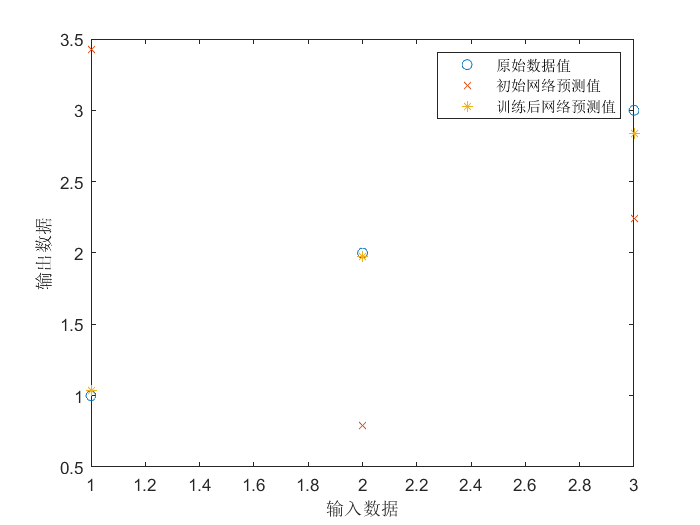



% 绘图
input=[1 2 3];
plot(input, target, 'o', input, pred1, 'x', input, pred2, '*')
legend('原始数据值','初始网络预测值','训练后网络预测值')
xlabel '输入数据'
ylabel '输出数据'


save('net3_3.mat','net');       % 将网络net保存为.mat文件，后面可直接调用




load('net3_3.mat');     % 导入之前保存的网络
%预测函数
fprintf('请输入测试数据x');

请输入测试数据x

x=[1 3 5 4]

x =      1     3     5     4


x=double_0_1(x);
x=x';
fprintf('输出测试结果y');

输出测试结果y

y=sim(net,x)

y = 1.1003

%1代表橙子 2代表香蕉 3代表苹果


if abs(y-1)<=0.2
    fprintf('这个水果是橙子');
elseif abs(y-2)<=0.2
    fprintf('这个水果是香蕉');
elseif abs(y-3)<=0.2 
    fprintf('这个水果是苹果');
else
    fprintf('这个水果不是橙子，苹果，香蕉中的任一种')
end

这个水果是橙子